# Title: Exercise 1

# Authors: Samuel Law & Rhys Miller

#### Define rotation matrix function

rot = @(radians) [cos(radians), sin(radians);
                 -sin(radians), cos(radians)];

#### Define hypotrochoid equations

R = 0.5; r = 0.1; d = 0.65; 
xh = @(theta) (((R-r)*cos(theta)) + (d*cos((R-r)*(theta/r))));
yh = @(theta) (((R-r)*sin(theta)) - (d*sin((R-r)*(theta/r))));

#### Generate points from hypotrochoid equations

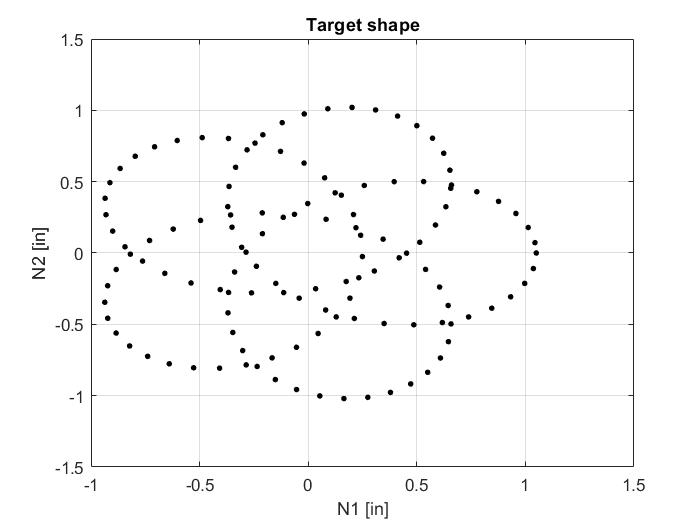

theta = [0:0.05:2*pi];
x_points = xh(theta);
y_points = yh(theta);
figure; hold off;
plot(x_points, y_points, '.k', 'MarkerSize', 10);
grid;
title("Target shape");
xlabel("N1 [in]");
ylabel("N2 [in]");

#### Define link lengths

L = 4;   % in
LA = 2.4;  % in
LB = 3.2;  % in
LC = 3.2;  % in
LD = 2.4;  % in

#### Define shape offset

off_set_N1 = -L/2;  % in 
off_set_N2 = 4;  % in

#### Generate point cloud

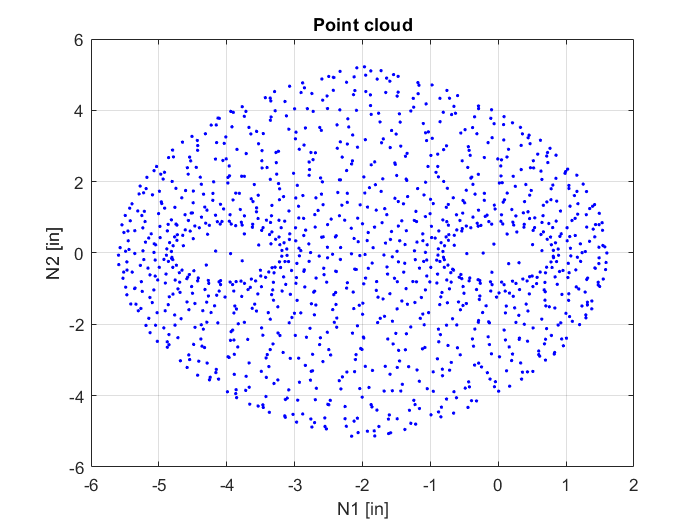

PND = [-L, 0];  % offset for the left motor;
results = []; 

% right arm through a full rotation
for alpha_1 = [0:0.2:2*pi]
    for alpha_2 = [0:0.2:2*pi]
        % solve for PNA
        RNA = rot(alpha_1);
        A1 = RNA(1,:);
        PNA = LA*A1;
        
        % solve for PAB
        RAB = rot(alpha_2)*RNA;
        B1 = RAB(1,:);
        PAB = LB*B1;
        
        % solve for PNB
        PNB = PNA + PAB;
        
        % check to see if PDB is 
        % longer than the arms 
        % could possibly reach
        if norm(PNB - PND) <= (LD+LC)
            results = [results; PNB];
        end   
    end
end

% left arm through a full rotation
for alpha_4 = [0:0.2:2*pi]
    for alpha_3 = [0:0.2:2*pi]
        % solve for PNC
        RND = rot(alpha_4);
        D1 = RND(1,:);
        PDC = LD*D1;
        
        % solve for PCB
        RDC = rot(alpha_3)*RND;
        C1 = RDC(1,:);
        PCB = LC*C1;
        
        % solve for PDB & PNB
        PDB = PDC + PCB;
        PNB = PND + PDC + PCB;
        
        % check to see if PDB is 
        % longer than the arms 
        % could possibly reach
        if norm(PNB) <= (LA+LB)
            results = [results; PNB];
        end   
    end
end

% plot the output
figure; hold off;
plot(results(:,1), results(:,2), '.b')
title("Point cloud")
xlabel("N1 [in]");
ylabel("N2 [in]");
grid;

#### Solve inverse kinematics

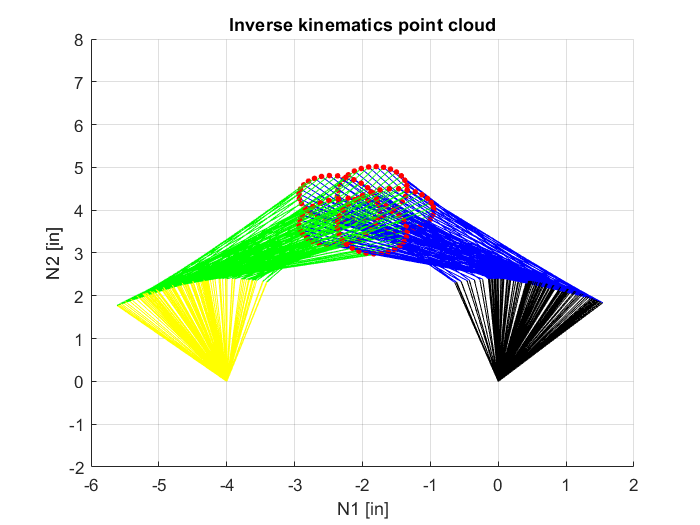

PND = [-L, 0];  % offset for the left motor;

figure; hold on;
for i = [1:1:length(x_points)]
    % define target position
    x = x_points(i) + off_set_N1;
    y = y_points(i) + off_set_N2;
    
    % solve for alpha_2 to achive target radius
    PXY = [x, y];
    R = norm(PXY);
    gamma = acos(((abs(R^2)) - (abs(LA^2)) - (abs(LB^2)))/(-2*LA*LB));
    alpha_2 = pi - gamma;  % alpha_2 > 0;
    
    % solve for alpha_1 from alpha 2
    PNA = [LA, 0];  % N1 direction
    RAB = rot(alpha_2);
    B1 = RAB(1,:);
    PAB = LB*B1;
    Shape = PNA + PAB;
    desired = atan2(PXY(2), PXY(1));
    current = atan2(Shape(2), Shape(1));
    alpha_1 = desired - current;
    
    % solve for alpha_3 to achive target radius
    R = norm(PXY - PND);
    gamma = acos(((R^2) - (LD^2) - (LC^2))/(-2*LD*LC));
    alpha_3 = -(pi - gamma);  % alpha_3 < 0;
    
    % solve for alpha_4 from alpha_3
    PDC = [LD, 0];  % N1 direction
    RCB = rot(alpha_3);
    C1 = RCB(1,:);
    PCB = LC*C1;
    Shape = PDC + PCB;  % the shape, not actual position
    desired = atan2(PXY(2) - PND(2), PXY(1) - PND(1));
    current = atan2(Shape(2), Shape(1));
    alpha_4 = desired - current;
    
    % define rotation matricies
    RNA = rot(alpha_1);
    RAB = rot(alpha_2)*RNA;
    RND = rot(alpha_4);
    RDC = rot(alpha_3)*RND;
    
    % define direction vector;
    A1 = RNA(1,:);
    A2 = RNA(2,:);
    B1 = RAB(1,:);
    B2 = RAB(2,:);
    D1 = RND(1,:);
    D2 = RND(2,:);
    C1 = RDC(1,:);
    C2 = RDC(2,:);
    
    % define position vectors
    PNA = LA*A1;
    PAB = LB*B1;
    PDC = LD*D1;
    PCB = LC*C1;
    
    % define points to plot
    Pa = PNA;
    Pb = PNA + PAB;
    Pc = PND + PDC;
    Pd = PND;

    % plot line approximation of bodies
    plot([0, Pa(1)],[0, Pa(2)], 'k');
    plot([Pa(1), Pb(1)],[Pa(2), Pb(2)], 'b');
    plot([PND(1), Pc(1)], [PND(2), Pc(2)], 'Y');
    plot([Pc(1), Pb(1)],[Pc(2), Pb(2)], 'g');
    plot(Pb(1), Pb(2), '.r', 'MarkerSize', 10);
    
end
hold off;

% format the plot
grid;
title("Inverse kinematics point cloud");
xlabel("N1 [in]");
ylabel("N2 [in]");
xlim([-6, 2]);
ylim([-2, 8]);